# 读取原始数据

%读取原始数据
name=read_xlsx_file_names("E:\课题最新进展\799FSRQIC\");
for i =1:length(name)
    csv_file_name = char(name(i)); % 记得替换成实际的文件名
    % 使用readmatrix函数读取CSV文件的数据，将其转换为数值矩阵
    data_matrix = readmatrix(strcat("E:\课题最新进展\799FSRQIC\",csv_file_name));
    %将源重新命名 
    base_name = csv_file_name(6:end - 4); % 获取去掉扩展名的文件名部分
    base_name=strrep(base_name,'+','_');
    base_name=strrep(base_name,'-','__');
    base_name=strrep(base_name,'.','____');
    data1.(base_name) = data_matrix;
    % 将数据矩阵存入结构体 data 中对应的字段
end
field_names = fieldnames(data1);
num_datasets = length(field_names);
field_names = fieldnames(data1);
%获取数据的时候需要将field_names(i)转为字符串后用data函数进行读取



save('sources', 'data1', 'data_matrix',"field_names","name");

%指定第几个源，field_names（第几个源）
load sources.mat
q=64
%q=linspace(101,176,76)
%for i =1:length(q)
    %temporary=field_names(q(i));
    temporary=field_names(q);
    temporary1=name(q);
    test1=data1.(char(temporary));

    % 更新后续使用的变量,x1,x2,y1、y2 分别为x轴负向误差、x轴正向误差、y轴负向误差、y轴正向误差
    nu=test1(:,5);
    nufu=test1(:,7);
    y1=test1(:,8);
    y2=y1;
    x1=test1(:,6);
    x2=x1;
    %figure
    %plot(nu,nufu,"r*")

%end

# 聚类部分代码

%聚类部分代码


%计算曲率
kappa = discrete_curvature(nu, nufu);

% 组合特征数据
cluster_data = [kappa, nu];

% 进行K-means聚类
[idx, c] = kmeans(cluster_data, 2, 'Replicates', 10); % 运行10次以减少初始中心的影响

% 计算每一类的均值
mean_nu_1 = mean(nu(idx == 1));
mean_nu_2 = mean(nu(idx == 2));

% 确保索引顺序合理（如必要，可以交换idx的定义，使idx=1总是对应低频峰）
if mean_nu_1 > mean_nu_2
    idx = 3 - idx; % 交换1和2的标签
end

% 计算每个类别的频率范围
nu_range_1 = [min(nu(idx == 1)), max(nu(idx == 1))];
nu_range_2 = [min(nu(idx == 2)), max(nu(idx == 2))];

% 处理重叠点，确保idx=1 和 idx=2 不重叠
overlap_idx = (nu >= nu_range_1(1) & nu <= nu_range_1(2)) & ...
    (nu >= nu_range_2(1) & nu <= nu_range_2(2));

% 将重叠区域的数据点重新归类
idx(overlap_idx) = -1; % 设为-1，表示需要重新分配

% 对于被置为-1的点，分配到距离均值更近的类别
for i = find(idx == -1)'
    if abs(nu(i) - mean_nu_1) < abs(nu(i) - mean_nu_2)
        idx(i) = 1;
    else
        idx(i) = 2;
    end
end

%disp(idx);4
data=[nu,nufu,x1,x2,y1,y2];
%disp(data);

% 找出第一个分类的最后一个点和第二个分类的第一个点的索引
last_point_cluster_1 = find(idx == 1, 1, 'last');
first_point_cluster_2 = find(idx == 2, 1, 'first');

% 获取这两个点的nu值
nu_last_cluster_1 = nu(last_point_cluster_1);
nu_first_cluster_2 = nu(first_point_cluster_2);

% 计算这两个nu值的平均数
single_boundary_point = (nu_last_cluster_1 + nu_first_cluster_2) / 2;

% 手动选择分界线
input_str = inputdlg('请输入手动分界线的nu值（若不手动选择请直接回车）：');
if ~isempty(input_str{1})
    manual_boundary = str2double(input_str{1});
    if ~isnan(manual_boundary)
        single_boundary_point = manual_boundary;
    else
        fprintf('输入无效，将使用自动计算的分界线。\n');
    end
end

disp(['最终分界线的nu值为：', num2str(single_boundary_point)]);

% 根据分界线重新分类
idx = zeros(size(nu));
idx(nu < single_boundary_point) = 1;
idx(nu >= single_boundary_point) = 2;

%disp(['重新分类后的idx值：']);
%disp(idx);
% 统计 idx 中 1 和 2 的数量
num_ones = sum(idx == 1);
num_twos = sum(idx == 2);

% 预先分配 data_syn 和 data_ic 的内存空间
data_syn = zeros(num_ones, size(data, 2));
data_ic = zeros(num_twos, size(data, 2));

% 初始化索引变量
syn_index = 1;
ic_index = 1;

% 根据聚类结果将 syn 与 ic 的数据点存储到相应的矩阵中
for i = 1:size(data, 1)
    if idx(i) == 1
        data_syn(syn_index, :) = data(i, :);
        syn_index = syn_index + 1;
    elseif idx(i) == 2
        data_ic(ic_index, :) = data(i, :);
        ic_index = ic_index + 1;
    end
end

% 去除多余的零行（如果有
data_syn = data_syn(1:syn_index - 1, :);
data_ic = data_ic(1:ic_index - 1, :);

plot(data_syn(:,1),data_syn(:,2),"r^")
hold on 
plot(data_ic(:,1),data_ic(:,2),"b^")
hold off 
% 修改同步和逆康普顿数据，指定某些点
% t_data = [data_syn(15,:);data_syn(16,:)];
% data_syn(15:16,:) = [];
% data_ic = [t_data;data_ic];

# 拟合的代码

%输入顶点坐标
%syn的
x0_syn_input = inputdlg('同步的顶点横坐标');
if ~isempty(x0_syn_input{1})
    x0_syn_input = str2double(x0_syn_input)';
else
    x0_syn_input = x0_syn;
end
%y0_syn_input = str2double(inputdlg('同步的顶点纵坐标'));-
y0_syn_input = inputdlg('同步的顶点纵坐标');
if ~isempty(y0_syn_input{1})
    y0_syn_input = str2double(y0_syn_input)';
else
    y0_syn_input = y0_syn;
end
% syn部分
input_ab_syn = inputdlg('输入同步部分需要转为正常的异常数据的索引，以逗号分隔：');
input_no_syn = inputdlg('输入同步部分需要转为异常的正常数据的索引，以逗号分隔：');
% 将输入的字符串转换为数值数组

aa= str2double(inputdlg('如果要自动异常数据剔除，输入1即可，否则输入其他数字'));
if ~isempty(input_ab_syn{1})
    input_ab_syn = str2double(split(input_ab_syn{1}, ","))';
else
    input_ab_syn = [];
end

if ~isempty(input_no_syn{1})
    input_no_syn = str2double(split(input_no_syn{1}, ","))';
else
    input_no_syn = [];
end



% 进行条件判断
if ~isempty(input_ab_syn) && isempty(input_no_syn)
    re_ab_syn = abnormal_syn(input_ab_syn, :);
    abnormal_syn(input_ab_syn, :) = [];
    normal_syn = [normal_syn; re_ab_syn];
    %[a_fit_syn, b_fit_syn, c_fit_syn] = monituihuo_plus2(normal_syn(:, 1), normal_syn(:, 2));
    [a_fit_syn, b_fit_syn, c_fit_syn,~,~,~,x0_syn, y0_syn,~] = MCSA(normal_syn,x0_syn_input, y0_syn_input,0);
elseif isempty(input_ab_syn) && ~isempty(input_no_syn)
    re_no_syn = normal_syn(input_no_syn, :);
    normal_syn(input_no_syn, :) = [];
    abnormal_syn = [abnormal_syn; re_no_syn]; 
    %[a_fit_syn, b_fit_syn, c_fit_syn] = monituihuo_plus2(normal_syn(:, 1), normal_syn(:, 2));
    [a_fit_syn, b_fit_syn, c_fit_syn,~,~,~,x0_syn, y0_syn,~] = MCSA(normal_syn,x0_syn_input, y0_syn_input,0);
elseif isempty(input_ab_syn) && isempty(input_no_syn)
    % 对 syn 成分进行异常数据点剔除
    %[normal_syn, abnormal_syn, a_fit_syn, b_fit_syn, c_fit_syn,x0_syn,y0_syn] = abnormal(data_syn,1, x0_syn_input, y0_syn_input); % (输入的待分类数据，剔除的次数>0，顶点横坐标，顶点纵坐标)
    %[normal_syn, abnormal_syn, a_fit_syn, b_fit_syn, c_fit_syn,~,~,~,x0_syn,y0_syn,nuc_syn] = abnormal_mc(data_syn,1, x0_syn_input, y0_syn_input,0) ;% (输入的待分类数据，剔除的次数>0，顶点横坐标，顶点纵坐标)
    if aa==1
        [normal_syn, abnormal_syn, a_fit_syn, b_fit_syn, c_fit_syn,~,~,~,x0_syn,y0_syn,nuc_syn] = abnormal_mc(data_syn,1, x0_syn_input, y0_syn_input,0) ;% (输入的待分类数据，剔除的次数>0，顶点横坐标，顶点纵坐标)                                                                                                              
    else
        %[~, ~, a_fit_ic, b_fit_ic, c_fit_ic,m_fit_ic,t_fit_ic,nu_fit_ic,x0_ic,y0_ic,nu0_ic] = abnormal_mc(normal_ic,0, x0_syn_input, y0_syn_input,nuc_ic_input); % (输入的待分类数据，顶点横坐标，顶点纵坐标)
        %[normal_syn, abnormal_syn, a_fit_syn, b_fit_syn, c_fit_syn,~,~,~,x0_syn,y0_syn,nuc_syn] = abnormal_mc(normal_syn,0, x0_syn_input, y0_syn_input,0) ;% (输入的待分类数据，剔除的次数>0，顶点横坐标，顶点纵坐标)
        [a_fit_syn, b_fit_syn, c_fit_syn,~,~,~,x0_syn, y0_syn,~] = MCSA(normal_syn,x0_syn_input, y0_syn_input,0);
    end


else
    disp("重新输入两种需要转正的索引吧，非零的那种索引最多一个，实在码不动了");
end
%对矩阵进行升序排序
normal_syn = sortrows(normal_syn, 1);
if ~isempty(abnormal_syn)
    abnormal_syn = sortrows(abnormal_syn,1);
end
%计算syn拟合优度R方
x_r_syn=normal_syn(:,1);
y_r_syn=(a_fit_syn.*x_r_syn.^2 + b_fit_syn.* x_r_syn + c_fit_syn);
y_r_mean_syn = mean(normal_syn(:,2));
SST_syn = sum((normal_syn(:,2)-y_r_mean_syn).^2);
RSS_syn =sum((normal_syn(:,2)-y_r_syn).^2);
R_squared_syn=1-RSS_syn/SST_syn;
disp(['syn拟合优度(R^2)为:' ,num2str(R_squared_syn)]);

%计算拟合优度X方，越接近1越好
dof_syn = 3;
N_syn = length(normal_syn(:,1));
X_2_syn = (1/(N_syn-dof_syn))*RSS_syn;
disp(['syn约化卡方X^2为：',num2str(X_2_syn)]);

%ic的
%x0_ic_input = str2double(inputdlg('逆康普顿的顶点横坐标'));
x0_ic_input = inputdlg('逆康普顿的顶点横坐标');
if ~isempty(x0_ic_input{1})
    x0_ic_input = str2double(x0_ic_input)';
else
    x0_ic_input = x0_ic;
end
%y0_ic_input = str2double(inputdlg('逆康普顿的顶点纵坐标'));
y0_ic_input = inputdlg('逆康普顿的顶点纵坐标');
if ~isempty(y0_ic_input{1})
    y0_ic_input = str2double(y0_ic_input)';

else
    y0_ic_input = y0_ic;
end
nuc_ic_input = inputdlg('特征频率预测值');
if ~isempty(nuc_ic_input{1})
    nuc_ic_input = str2double(nuc_ic_input)';
else
    nuc_ic_input = nu0_ic;
end


%%IC部分

input_ab_ic = inputdlg('输入逆康普顿部分需要转为正常的异常数据的索引，以逗号分隔：');
input_no_ic = inputdlg('输入逆康普顿部分需要转为异常的正常数据的索引，以逗号分隔：');


%对data_ic拟合，gg=1；对normal——ic拟合gg=2
gg = str2double(inputdlg('如果要自动异常数据剔除，输入1即可，否则输入其他数字'));
% 将输入的字符串转换为数值数组
if ~isempty(input_ab_ic{1})
    input_ab_ic = str2double(split(input_ab_ic{1}, ","))';
else
    input_ab_ic = [];
end
if ~isempty(input_no_ic{1})
    input_no_ic = str2double(split(input_no_ic{1}, ","))';
else
    input_no_ic = [];
end
% 进行条件判断
if ~isempty(input_ab_ic) && isempty(input_no_ic)
    re_ab_ic = abnormal_ic(input_ab_ic, :);
    abnormal_ic(input_ab_ic, :) = [];
    normal_ic = [normal_ic; re_ab_ic];
    %[x_pred, y_pred,a_fit_ic, b_fit_ic, c_fit_ic,t_fit_ic,m_fit_ic,nu_fit_ic] = LPPL_ic(normal_ic);
    [a_fit_ic,b_fit_ic,c_fit_ic,m_fit_ic,t_fit_ic,nu_fit_ic,x0_ic,y0_ic,nu0_ic] = MCSA(normal_ic,x0_ic_input,y0_ic_input,nuc_ic_input);
elseif isempty(input_ab_ic) && ~isempty(input_no_ic)
    re_no_ic = normal_ic(input_no_ic, :);
    normal_ic(input_no_ic, :) = [];
    abnormal_ic = [abnormal_ic; re_no_ic]; 
    [a_fit_ic,b_fit_ic,c_fit_ic,m_fit_ic,t_fit_ic,nu_fit_ic,x0_ic,y0_ic,nu0_ic] = MCSA(normal_ic,x0_ic_input,y0_ic_input,nuc_ic_input);
elseif isempty(input_ab_ic) && isempty(input_no_ic)
    % 对 ic 成分进行异常数据点剔除
    %[normal_ic, abnormal_ic, x_pred_ic, y_pred_ic, a_fit_ic, b_fit_ic, c_fit_ic,nu_fit_ic,m_fit_ic,t_fit_ic,x0_ic,y0_ic] = combined_analysis(data_ic,2,x0_ic_input,y0_ic_input);%里面也是需要改顶点的恒纵坐标的    
    %[normal_ic, abnormal_ic, x_pred_ic, y_pred_ic, a_fit_ic, b_fit_ic, c_fit_ic,nu_fit_ic,m_fit_ic,t_fit_ic,x0_ic,y0_ic] = combined_analysis(data_ic,2,x0_ic_input,y0_ic_input);%里面也是需要改顶点的恒纵坐标的
    if gg==1
        [normal_ic, abnormal_ic, a_fit_ic, b_fit_ic, c_fit_ic,m_fit_ic,t_fit_ic,nu_fit_ic,x0_ic,y0_ic,nu0_ic] = abnormal_mc(data_ic,1, x0_ic_input, y0_ic_input,nuc_ic_input); % (输入的待分类数据，顶点横坐标，顶点纵坐标)
                                                                                                                
    else
        %[~, ~, a_fit_ic, b_fit_ic, c_fit_ic,m_fit_ic,t_fit_ic,nu_fit_ic,x0_ic,y0_ic,nu0_ic] = abnormal_mc(normal_ic,0, x0_syn_input, y0_syn_input,nuc_ic_input); % (输入的待分类数据，顶点横坐标，顶点纵坐标)
        [a_fit_ic,b_fit_ic,c_fit_ic,m_fit_ic,t_fit_ic,nu_fit_ic,x0_ic,y0_ic,nu0_ic] = MCSA(normal_ic,x0_ic_input,y0_ic_input,nuc_ic_input);
    end
else
    disp("重新输入两种需要转正的索引吧，非零的那种索引最多一个，实在码不动了");
end
%矩阵升序排序
normal_ic = sortrows(normal_ic, 1);
if ~isempty(abnormal_ic)
    abnormal_ic = sortrows(abnormal_ic,1);
end
% %计算ic拟合优度R2和X2
if ~isempty(nu_fit_ic)
    id_x_pl = find(normal_ic(:,1) <= nu_fit_ic);
    if  ~isempty(id_x_pl)
        %de_x=normal_ic(max(id_x_pl),1)
        x_r_ic_pl=[normal_ic(1:id_x_pl(end),1)];
        x_r_ic_lp=[normal_ic(id_x_pl(end)+1:length(normal_ic(:,1)),1)];
        x_r_ic=normal_ic(:,1);
        y_r_ic_pl=(m_fit_ic.*x_r_ic_pl+t_fit_ic);
        y_r_ic_lp=(a_fit_ic.*x_r_ic_lp.^2 + b_fit_ic.* x_r_ic_lp + c_fit_ic);
        y_r_ic=[y_r_ic_pl;y_r_ic_lp];
    else
        x_r_ic=normal_ic(:,1);
        y_r_ic=(a_fit_ic.*x_r_ic.^2 + b_fit_ic.* x_r_ic + c_fit_ic);
    end
    y_r_mean_ic = mean(normal_ic(:,2));
    SST_ic = sum((normal_ic(:,2)-y_r_mean_ic).^2);
    RSS_ic =sum((normal_ic(:,2)-y_r_ic).^2);
    R_squared_ic=1-RSS_ic/SST_ic;
    disp(['IC拟合优度(R^2)为:' ,num2str(R_squared_ic)]);
    %计算拟合优度X方，越接近1越好
    dof_ic = 4;
    N_ic = length(normal_ic(:,1));
    X_2_ic = (1/(N_ic-dof_ic))*RSS_ic;
    disp(['syn约化卡方X^2为：',num2str(X_2_ic)]);
else
    x_r_ic=normal_ic(:,1);
    y_r_ic=(a_fit_ic.*x_r_ic.^2 + b_fit_ic.* x_r_ic + c_fit_ic);
    y_r_mean_ic = mean(normal_ic(:,2));
    SST_ic = sum((normal_ic(:,2)-y_r_mean_ic).^2);
    RSS_ic =sum((normal_ic(:,2)-y_r_ic).^2);
    R_squared_ic=1-RSS_ic/SST_ic;
    disp(['ic拟合优度(R^2)为:' ,num2str(R_squared_ic)]);
    %计算拟合优度X方，越接近1越好
    dof_ic = 4;
    N_ic = length(normal_ic(:,1));
    X_2_ic = (1/(N_ic-dof_ic))*RSS_ic;
    disp(['syn约化卡方X^2为：',num2str(X_2_ic)]);
end

ic拟合优度(R^2)为:0.96856


syn约化卡方X^2为：0.0093534


# 绘图部分代码

disp(['ic拟合优度(R^2)为:' ,num2str(R_squared_ic)]);

ic拟合优度(R^2)为:0.96856


disp(['ic(RSS)为:' ,num2str(RSS_ic)]);

ic(RSS)为:0.0093534


disp(['ic(SST)为:' ,num2str(SST_ic)]);

ic(SST)为:0.29755


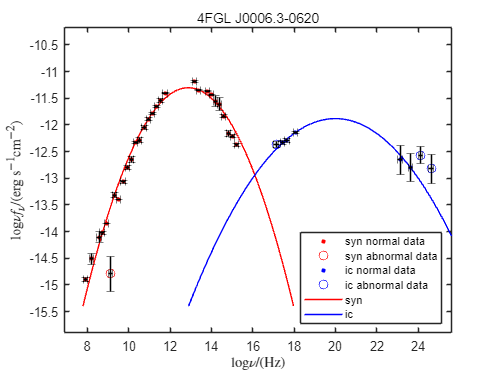

%%找出拟合的范围（取正常函数值的最小值作为标准）
y_min=min([normal_syn(:,2);normal_ic(:,2)])-0.5;

%拟合syn成分
x_syn_max=(1/(2*a_fit_syn))*(-b_fit_syn-sqrt((b_fit_syn)^2-4*a_fit_syn*(c_fit_syn-y_min)));
x_syn_min=(1/(2*a_fit_syn))*(-b_fit_syn+sqrt((b_fit_syn)^2-4*a_fit_syn*(c_fit_syn-y_min)));
%x_syn = linspace(min(normal_syn(:,1)),max(normal_syn(:,1)),150);
x_syn = linspace(x_syn_min,x_syn_max,150);
y_syn = a_fit_syn.* x_syn.^2 + b_fit_syn.* x_syn + c_fit_syn;
%拟合ic成分2
if ~isempty(nu_fit_ic)
    x_ic_max=(1/(2*a_fit_ic))*(-b_fit_ic-sqrt((b_fit_ic)^2-4*a_fit_ic*(c_fit_ic-y_min)));
    x_ic_lp = linspace(nu_fit_ic,x_ic_max,150);
    y_ic_lp = a_fit_ic.* x_ic_lp.^2 + b_fit_ic.* x_ic_lp + c_fit_ic;
    x_ic_min=(y_min-t_fit_ic)/m_fit_ic;
    x_ic_pl = linspace(x_ic_min,nu_fit_ic,150);
    y_ic_pl = m_fit_ic.*x_ic_pl+t_fit_ic;
    x_ic = [x_ic_pl,x_ic_lp];
    y_ic = [y_ic_pl,y_ic_lp];
else
    x_ic_max=(1/(2*a_fit_ic))*(-b_fit_ic-sqrt((b_fit_ic)^2-4*a_fit_ic*(c_fit_ic-y_min)));
    x_ic_min=(1/(2*a_fit_ic))*(-b_fit_ic+sqrt((b_fit_ic)^2-4*a_fit_ic*(c_fit_ic-y_min)));

    x_ic = linspace(x_ic_min,x_ic_max,150);
    y_ic = a_fit_ic.* x_ic.^2 + b_fit_ic.* x_ic + c_fit_ic;
end

%输出拟合优度

figure;
%绘制syn正常数据点
plot(normal_syn(:,1), normal_syn(:,2),'r.','MarkerSize',10);
hold on;

%绘制syn异常数据点
if ~isempty(abnormal_syn)
    plot(abnormal_syn(:,1),abnormal_syn(:,2),'ro','MarkerSize',7);
    hold on;
end
%绘制ic正常数据点
plot(normal_ic(:,1), normal_ic(:,2),'b.','MarkerSize',10);
hold on;

%绘制ic异常数据点
if ~isempty(abnormal_ic)
    plot(abnormal_ic(:,1), abnormal_ic(:,2),'bo','MarkerSize',7);
    hold on;
end
%绘制 syn 成分的曲线
plot(x_syn,y_syn,'r-','LineWidth',0.5,'DisplayName','syn');
hold on

% 绘制 ic 成分的曲线
plot(x_ic,y_ic,"b-",'LineWidth',0.5,'DisplayName','ic');
hold on

for i = 1:size(normal_syn,1)
    errorbar(normal_syn(i,1),normal_syn(i,2),normal_syn(i,5),normal_syn(i,6),normal_syn(i,3),normal_syn(i,4), 'k', 'LineStyle', 'none','DisplayName','');
    hold on;
end

for i = 1:size(abnormal_syn,1)
    errorbar(abnormal_syn(i,1),abnormal_syn(i,2),abnormal_syn(i,5),abnormal_syn(i,6),abnormal_syn(i,3),abnormal_syn(i,4), 'k', 'LineStyle', 'none','DisplayName','');
    hold on;
end

for i = 1:size(normal_ic,1)
    errorbar(normal_ic(i,1),normal_ic(i,2),normal_ic(i,5),normal_ic(i,6),normal_ic(i,3),normal_ic(i,4), 'k', 'LineStyle', 'none','DisplayName','');
    hold on;
end

for i = 1:size(abnormal_ic,1)
    errorbar(abnormal_ic(i,1),abnormal_ic(i,2),abnormal_ic(i,5),abnormal_ic(i,6),abnormal_ic(i,3),abnormal_ic(i,4), 'k', 'LineStyle', 'none','DisplayName','');
    hold on;
end

hold on;

% 假设 xx_syn、yy_syn、xx_ic、yy_ic 已正确定义，若未定义则可根据实际情况修改
% 若未定义，可考虑使用现有的数据来设置坐标轴范围

%%两边的异常成分都有值的时候
% x_min = min([min(normal_syn(:,1)), min(abnormal_syn(:,1)), min(normal_ic(:,1)), min(abnormal_ic(:,1))]);
% x_max = max([max(normal_syn(:,1)), max(abnormal_syn(:,1)), max(normal_ic(:,1)), max(abnormal_ic(:,1))]);
% y_min = min([min(normal_syn(:,2)), min(abnormal_syn(:,2)), min(normal_ic(:,2)), min(abnormal_ic(:,2))]);
% y_max = max([max(normal_syn(:,2)), max(abnormal_syn(:,2)), max(normal_ic(:,2)), max(abnormal_ic(:,2))]);

%ic的异常成分没有
% x_min = min([min(normal_syn(:,1)), min(abnormal_syn(:,1)), min(normal_ic(:,1))]);
% x_max = max([max(normal_syn(:,1)), max(abnormal_syn(:,1)), max(normal_ic(:,1))]);
% y_min = min([min(normal_syn(:,2)), min(abnormal_syn(:,2)), min(normal_ic(:,2))]);
% y_max = max([max(normal_syn(:,2)), max(abnormal_syn(:,2)), max(normal_ic(:,2))]);
%syn的异常成分没有
% x_min = min([min(normal_syn(:,1)), min(abnormal_ic(:,1)), min(normal_ic(:,1))]);
% x_max = max([max(normal_syn(:,1)), max(abnormal_ic(:,1)), max(normal_ic(:,1))]);
% y_min = min([min(normal_syn(:,2)), min(abnormal_ic(:,2)), min(normal_ic(:,2))]);
% y_max = max([max(normal_syn(:,2)), max(abnormal_ic(:,2)), max(normal_ic(:,2))]);
%%两边异常都没有
% x_min = min([min(normal_syn(:,1)),  min(normal_ic(:,1))]);
% x_max = max([max(normal_syn(:,1)),  max(normal_ic(:,1))]);
% y_min = min([min(normal_syn(:,2)), min(normal_ic(:,2))]);
% y_max = max([max(normal_syn(:,2)),  max(normal_ic(:,2))]);


%%两边的异常成分都有值的时候
if ~isempty(abnormal_ic)&&~isempty(abnormal_syn)
    x_min = min([min(normal_syn(:,1)), min(abnormal_syn(:,1)), min(normal_ic(:,1)), min(abnormal_ic(:,1))]);
    x_max = max([max(normal_syn(:,1)), max(abnormal_syn(:,1)), max(normal_ic(:,1)), max(abnormal_ic(:,1))]);
    y_min = min([min(normal_syn(:,2)), min(abnormal_syn(:,2)), min(normal_ic(:,2)), min(abnormal_ic(:,2))]);
    y_max = max([max(normal_syn(:,2)), max(abnormal_syn(:,2)), max(normal_ic(:,2)), max(abnormal_ic(:,2))]);
   
%ic的异常成分没有
elseif isempty(abnormal_ic)&&~isempty(abnormal_syn)
    x_min = min([min(normal_syn(:,1)), min(abnormal_syn(:,1)), min(normal_ic(:,1))]);
    x_max = max([max(normal_syn(:,1)), max(abnormal_syn(:,1)), max(normal_ic(:,1))]);
    y_min = min([min(normal_syn(:,2)), min(abnormal_syn(:,2)), min(normal_ic(:,2))]);
    y_max = max([max(normal_syn(:,2)), max(abnormal_syn(:,2)), max(normal_ic(:,2))]);
%syn的异常成分没有
elseif isempty(abnormal_syn)&&~isempty(abnormal_ic) 
    x_min = min([min(normal_syn(:,1)), min(abnormal_ic(:,1)), min(normal_ic(:,1))]);
    x_max = max([max(normal_syn(:,1)), max(abnormal_ic(:,1)), max(normal_ic(:,1))]);
    y_min = min([min(normal_syn(:,2)), min(abnormal_ic(:,2)), min(normal_ic(:,2))]);
    y_max = max([max(normal_syn(:,2)), max(abnormal_ic(:,2)), max(normal_ic(:,2))]);
%%两边异常都没有
else
    x_min = min([min(normal_syn(:,1)),  min(normal_ic(:,1))]);
    x_max = max([max(normal_syn(:,1)),  max(normal_ic(:,1))]);
    y_min = min([min(normal_syn(:,2)), min(normal_ic(:,2))]);
    y_max = max([max(normal_syn(:,2)),  max(normal_ic(:,2))]);
end




% 设置坐标轴范围
xlim([x_min - 1, x_max + 1]);
ylim([y_min - 1, y_max + 1]);


% 添加坐标轴标签
xlabel('$\rm{log}\nu/(\rm{Hz})$', 'Interpreter', 'latex');
ylabel('$\rm{log}{\nu} \mathit{f}_\nu/(\rm{erg\,s^{-1}cm^{-2}})$', 'Interpreter', 'latex');
% xlabel('log(v)');
% ylabel('log(vF(v))');
% 
% source_name=char(temporary1);
% source_name=source_name(1:end - 5);

%去除空格,增加空格统一格式
source_name=char(temporary1);
source_name = source_name(~isspace(source_name));
source_name=source_name(1:end - 5);
source_name = [source_name(1:4) ' ' source_name(4+1:end)];

% 添加图形标题
title(source_name);
hold on;

%添加图例

% legend('syn normal data','syn abnormal data','ic normal data','ic abnormal data','syn','ic','Location','southeast');
% hold off;


%添加图例
if ~isempty(abnormal_ic)&&~isempty(abnormal_syn)
    legend('syn normal data','syn abnormal data','ic normal data','ic abnormal data','syn','ic','Location','southeast');
    hold off;
elseif isempty(abnormal_syn)&&~isempty(abnormal_ic)
    legend('syn normal data','ic normal data','ic abnormal data','syn','ic','Location','southeast');
    hold off;
elseif isempty(abnormal_ic)&&~isempty(abnormal_syn)
    legend('syn normal data','syn abnormal data','ic normal data','syn','ic','Location','southeast');
    hold off;
else
    legend('syn normal data','ic normal data','syn','ic','Location','southeast');
    hold off;
end

# 计算拟合参数并且保存

% 指定保存图片的文件夹路径
save_folder ="E:\课题最新进展\result_t"; % 这里替换为你实际想要保存的文件夹路径
if ~exist(save_folder, 'dir') % 检查文件夹是否存在
    mkdir(save_folder); % 如果不存在就创建它
end
% 定义保存的文件名（包含路径和扩展名.jpg）
source_name=char(temporary1);
source_name=source_name(1:end - 5);
source_name = [source_name '.pdf'];
file_name = fullfile(save_folder, source_name);
print('-dpdf', file_name);

%计算alpha*、beta*、nu_0、取k_syn=10^-28、k_ssc=k_ec=10^-38


%同步成分：
k_syn=10^(-28);
beta_syn=-a_fit_syn;
nu_star_syn=10^((-1+b_fit_syn)+sqrt(((b_fit_syn-1)^2-4*beta_syn*(-c_fit_syn+log10(k_syn))))/(2*beta_syn));
alpha_star_syn=1-b_fit_syn-2*beta_syn*log10(nu_star_syn);
%IC成分：
k_ic=10^(-38);
beta_ic=-a_fit_ic;
nu_star_ic=10^((-1+b_fit_ic)+sqrt(((b_fit_ic-1)^2-4*beta_ic*(-c_fit_ic+log10(k_ic))))/(2*beta_ic));
alpha_star_ic=1-b_fit_ic-2*beta_ic*log10(nu_star_ic);

%P1：同步辐射光谱曲率；P2：同步辐射峰值频率；P3：同步辐射峰值流量
%P4：逆康普顿光谱曲率；P5：逆康普顿峰值频率；P6：逆康普顿峰值流量
p1=a_fit_syn;
p2=(-1)*(b_fit_syn/(2*a_fit_syn));
p3=c_fit_syn-((b_fit_syn^2)/(4*a_fit_syn));

p4=a_fit_ic;
p5=(-1)*(b_fit_ic/(2*a_fit_ic));
p6=c_fit_ic-((b_fit_ic^2)/(4*a_fit_ic));
%y=p1(x-p2)^2+p3
%y=ax^2+bx+c
%计算峰值处的谱指数
alpha_peak_syn=1;
alpha_peak_ic=1;
%保存喷流物理参数




% 首先确保保存文件夹存在，如果不存在则创建它
save_folder = "E:\课题最新进展\result_t"; % 这里替换为你实际想要保存的文件夹路径，如果是绝对路径如'E:\天文喷流物理参数\聚类结果'也可以
if ~exist(save_folder, 'dir')
    mkdir(save_folder);
end

% 组合完整的文件名（包含路径和扩展名.xlsx）
source_name1=char(temporary1);
source_name1=source_name1(1:end - 5);
file_name1 = fullfile(save_folder, [source_name '.xlsx']);

results_table = table();

results_table.alpha_star_syn = alpha_star_syn;
results_table.beta_syn = beta_syn;
results_table.nu_star_syn = nu_star_syn;
results_table.p1 = p1;
results_table.p2 = p2;
results_table.p3 = p3;
results_table.alpha_peak_syn = alpha_peak_syn;
results_table.R2_syn = R_squared_syn;
results_table.X2_syn = X_2_syn;
results_table.alpha_star_ic = alpha_star_ic;
results_table.beta_ic = beta_ic;
results_table.nu_star_ic = nu_star_ic;
results_table.p4 = p4;
results_table.p5 = p5;
results_table.p6 = p6;
results_table.R2_ic = R_squared_ic;
results_table.X2_ic = X_2_ic;
results_table.alpha_peak_ic = alpha_peak_ic;
results_table.fenjie = single_boundary_point;
% 使用writetable函数将表格数据保存到Excel文件中
writetable(results_table, file_name1);

%顶点指定保存的文件名
file_name1 = fullfile(save_folder, [source_name '.txt'])
%保存到txt文件中
dlmwrite(file_name1, [x0_syn,y0_syn; x0_ic, y0_ic;nu0_ic,nu0_ic;single_boundary_point,single_boundary_point], 'delimiter', '\t')

% end

save_folder_mat = "E:\课题最新进展\result_t";
if ~exist(save_folder_mat, 'dir')
    mkdir(save_folder_mat);
end
save (fullfile( save_folder_mat,[source_name '.mat']));
clc,clear;